% Moment based kalman filter
clear
close all

datasetFolder="./MRCLAM_Dataset1";
robotNumber = "Robot1";

% true data
groundTruth = importdata(strcat(datasetFolder,"/",robotNumber,"_Groundtruth.dat"))

groundTruth = フィールドをもつ struct :
        data: [81877×4 double]
    textdata: {4×1 cell}


groundTruth.data = groundTruth.data(1:10000,:);
time = groundTruth.data(:,1);
trueX = groundTruth.data(:,2);
trueY = groundTruth.data(:,3);
trueTheta = groundTruth.data(:,4);

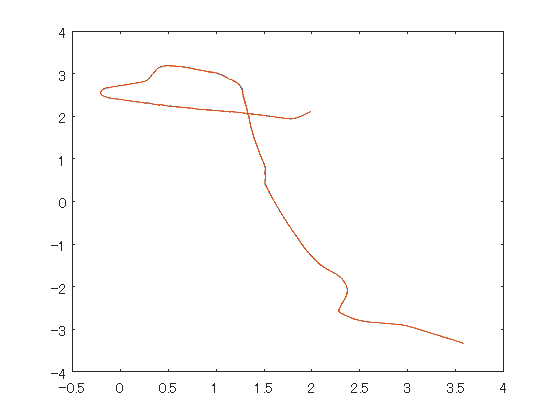

% observation data 
rng('default');
rng(1);
observationMu = 0;
observationSigma = 0.001;
observationNoise = random('Normal',observationMu,observationSigma,[size(time,1),3]);
observationX = trueX + observationNoise(:,1);
observationY = trueY + observationNoise(:,2);
observationTheta = trueTheta + observationNoise(:,3);
plot(trueX,trueY,observationX,observationY)

% plot(time,observationX-trueX)

% odometry data
odom = importdata(strcat(datasetFolder,"/",robotNumber,"_Odometry.dat"));
odomTime = odom.data(:,1);
odomVel = odom.data(:,2);
odomAngVel = odom.data(:,3);


temp1 = array2timetable(odom.data(:,2:3),'RowTimes',seconds(odomTime))

temp1 = 97890×2 timetable
        Time         Var1     Var2 
    _____________    _____    _____

    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074     0.23
    1.2483e+09 秒    0.074     0.23
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.227
    1.2483e+09 秒    0.074    0.224
    1.2483e+09 秒    0.074    0.224
    1.2483e+09 秒    0.074     0.22
    1.2483e+09 秒    0.074    0.216


dt = seconds(0.01);
temp2 = retime(temp1,'regular','previous','TimeStep',dt)

temp2 = 149049×2 timetable
        Time         Var1     Var2 
    _____________    _____    _____

    1.2483e+09 秒      NaN      NaN
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
    1.2483e+09 秒    0.074    0.229
